# Design of a Controller for a Dynamic System with an LHP Uncertain Pole

## Description of the Feedback Control System

Consider the feedback control system described by the block-scheme shown in the following figure   

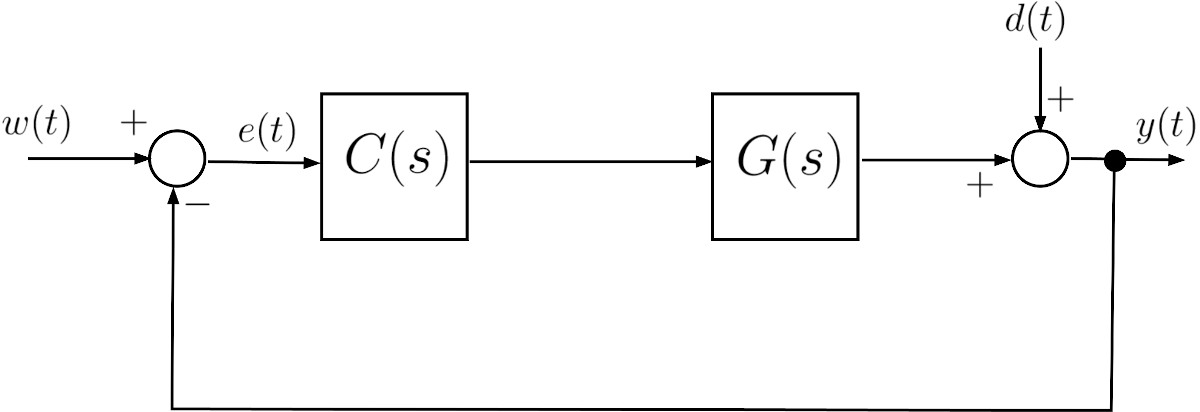	

where $G(s)$ is given by                


$$G(s) = 9\, \frac{1+0.1\,s}{1+\tau\,s}\,,\quad \tau \in \left[0.5\,,\; 10\right]$$
	

## **Question**		

**Q1**: Assume $d(t) = 0\; \forall t$.Design a controller $C(s) $ such that all following requirements are simultaneously met: 

- $t_s \le 10 \,\text{s}$  , where $t_s$ is the settling time at $1\,\%$ ;  

- $\left| e(\infty)\right| =0$ for $w(t) = \mathbf{1}(t)$, where $\mathbf{1}(t)$ denotes the unit step function.

- The phase margin satisfies: $\varphi_m \ge 40^{\degree}$.

[Excerpt from the written examination on date 2023/02/06]	

## Foreword to the Provided Solution

The proposed problem admits to more than one possible solution. The proposed solution is not the only admissible solution (in fact, the problem admits to infinite solutions), nor is it optimal. It is only a simple solution that can be obtained using the tools available in MATLAB's Control System Toolbox.

You are encouraged to solve the problem by finding alternative solutions and comparing the performance of the control system using your solution with those obtained using the proposed solution in this live script.  				

## Solution 

Let's define the transfer function of the process $G(s)$ and configure the MATLAB Search Path, by adding the folder containing the M-code able to compute and plot the asymptotic approximation of the Bode diagrams of the frequency response of a given transfer function.

clear

% adding folders (and subfolders) to search path
addpath(genpath('BodeDiagram/'))

% let's define the transfer function builder element
s=tf('s');

